close all;
clear all;
load('cmap_mat.mat');
Site= 'NirEeliyahu';
director=(['C:\Users\Stav\Desktop\school\2\Research\hohoba\results\plot\']);
shp_file=dir([director '*.mat']);
[files{1:numel(shp_file)}]=shp_file(:).name ;
N = length(files);
Plots_Array = cell(N,1);
files=files'; %array with all the name files



figure
for i=1:length(files)
    clearvars -except i Plots_Array director files cmap_mat
    plot_PathName=[director files{i}];
    plot_num = extractBetween(files{i},'_','.mat');
    plot_num=plot_num(1,1);
    Plot_title= ['Plot ' char(plot_num)];
    [TIR,tfw]= open_Plot_Data(plot_PathName);

    newTIR= TIR;
    newTIR(find(newTIR<0.1))=0;
    im_scaled = newTIR;
    newTIR(find(newTIR>80))=0;
    minT = min(newTIR(:));
    if minT<15
        minT =15;
    end
    maxT = max (newTIR(:));
    newTIR(find(TIR>60))=maxT;
    histogram(TIR(:),'BinWidth', 0.1,'BinLimits', [minT maxT],'FaceAlpha',0.5,'EdgeColor','none');

Segmentation with Cont_Max_Flow_Cut with the characteristic values of the classes defining parameters to Cont_Max_Flow_Cut

    [UB_canopy,UB_background] = Find_Peaks(newTIR(:));
    if(abs(UB_background-UB_canopy)==0)
        UB_background=prctile(TIR(:),90)
    end
    CMF_input =newTIR;
    CMF_input(find(newTIR==0))=maxT;
    [CMF, erriter, it, timet] = Cont_Max_Flow_Cut(CMF_input,UB_canopy,UB_background);
    segmented_CMF = zeros(size(CMF));
    segmented_CMF((CMF<0.5))=1;%0.3

Segmentation with Otsu

    [IDX,sep] = otsu(newTIR((newTIR>0)),2);
    segmented_Otsu=newTIR;
    ind=find(newTIR>0);
    segmented_Otsu(ind((IDX==2)))=0;

 Segmentation with FWHM 

    level = 0.5;
    limit_of_left_gauss= UB_canopy+ ((UB_background - UB_canopy)/2);
    thresh_FWHM = FWHM(newTIR((newTIR>0)),level,limit_of_left_gauss);
    segmented_FWHM = zeros(size(newTIR));
    segmented_FWHM(find(newTIR<=thresh_FWHM &newTIR>1))=1;

Display all methdos - Otsu, Cont_Max_Flow_Cut and FWHM

    % t = ['CMF:canopy,',num2str(UB_canopy),' background:',num2str(UB_background)];
    main_title = ('Comparison of the segmentation methods');
    Show_all(segmented_CMF,segmented_Otsu,segmented_FWHM,'CMF','Otsu','FWHM',true,main_title);

Integration of the methods

    unionMin_CMF_Otsu = min(segmented_CMF,segmented_Otsu);
    unionMax_CMF_Otsu = max(segmented_CMF,segmented_Otsu);
    unionMin_Otsu_FWHM = min(segmented_FWHM,segmented_Otsu);
    unionMax_Otsu_FWHM = max(segmented_FWHM,segmented_Otsu);
    unionMin_CMF_FWHM = min(segmented_FWHM,segmented_CMF);
    unionMax_CMF_FWHM = max(segmented_FWHM,segmented_CMF);

    All unionMin Integration

    main_title = ('UnionMin Integration');
    Show_all(unionMin_CMF_Otsu,unionMin_CMF_FWHM,unionMin_Otsu_FWHM,'Otsu-CMF','CMF-FWHM','Otsu-FWHM',true,main_title);

All unionMax Integration

    main_title = ('UnionMax Integration');
    Show_all(unionMax_CMF_Otsu,unionMax_CMF_FWHM,unionMax_Otsu_FWHM,'Otsu-CMF','CMF-FWHM','Otsu-FWHM',true,main_title);

Returning to the original canopy values to further analysis

    Choosen_segmentaation = unionMin_CMF_Otsu;
    se = strel('disk',10);%10 Kedma
%     Check about different sizes
    Choosen_segmentaation = imopen(Choosen_segmentaation,se);
    figure, imshow(Choosen_segmentaation)
    
    canopy_indices = find(Choosen_segmentaation == 1);
    canopy_seg = newTIR.*Choosen_segmentaation;
    newMin= min(canopy_seg(canopy_indices))
    newMax=max(canopy_seg(canopy_indices))
    figure(),imagesc(canopy_seg,[newMin newMax]);
    colormap(cmap_mat);
    colorbar(); 

watershed

    bw=logical(Choosen_segmentaation);
    figure()
    imshow(bw)
    title('Segmentation mask = bw' );

%     bw2 = ~bwareaopen(~bw, 10);
%     figure()
%     imshow(bw2)
%     title('filtered image after removing small objects= bw2');

    D = -bwdist(~bw);
    figure()
    imshow(D,[])
    title('Distance matrix of bw = D');

    Ld = watershed(D);
    figure()
    imshow(label2rgb(Ld))
    title('Distance matrix after watershed = Ld');

    bw2 = bw;
    bw2(Ld == 0) = 0;
    figure()
    imshow(bw2)
    title('bw after removing logical boreders watershed (Ld) = bw2');
  

computes the extended-minima transform, which is the regional minima of the `H`-minima transform. Regional minima are connected components of pixels with a constant intensity value, and whose external boundary pixels all have a higher value.

    mask = imextendedmin(D,2);
    figure()
    imshowpair(bw,mask,'blend')
    title('Segmentation mask and mask created by imextendedmin(D,2) = mask');


modifies the grayscale mask image D using morphological reconstruction so it only has regional minima wherever binary marker image mask is nonzero.

    D2 = imimposemin(D,mask);
    figure()
    imagesc(D2)
    title('imimposemin(D,mask)=D2');
    

    watershed on D2

    Ld2 = watershed(D2);
    figure()
    imshow(label2rgb(Ld2))
    title('watershed on D2 = Ld2');
    
    bw3 = bw;
    bw3(Ld2 == 0) = 0;
    figure()
    imshow(bw3)
    title('The segmentation mask after removing logical boreders from Ld2 = BW3');

  Find connected components in binary image bw3

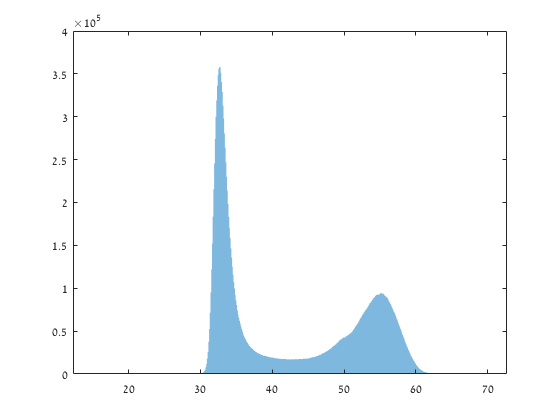

UB_canopy = 33.4110

UB_background = 55.1669

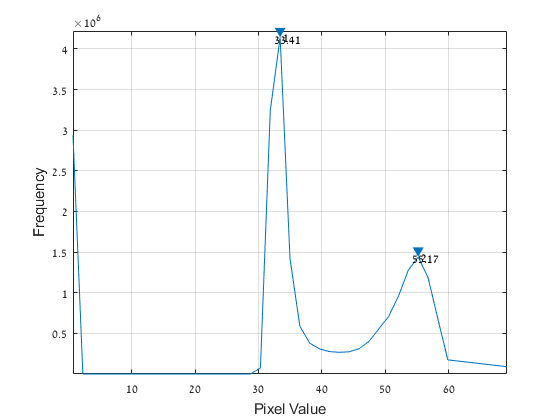

Elapsed time is 62.809631 seconds.


timet = 62.8552

number of iterations = 19. 


   115

     1

    -1

   111

ttrail (x2)=
   33.9444



ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0 0 0.3333 1]
            Units: 'normalized'

  Show all properties


ax =   1×2 Axes array:

    Axes    Axes


ax =   1×3 Axes array:

    Axes    Axes    Axes


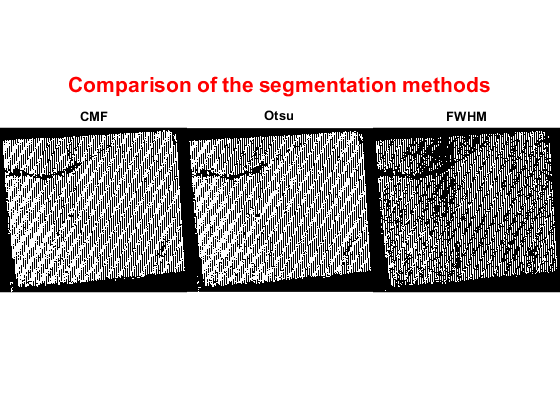

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0 0 0.3333 1]
            Units: 'normalized'

  Show all properties


ax =   1×2 Axes array:

    Axes    Axes


ax =   1×3 Axes array:

    Axes    Axes    Axes


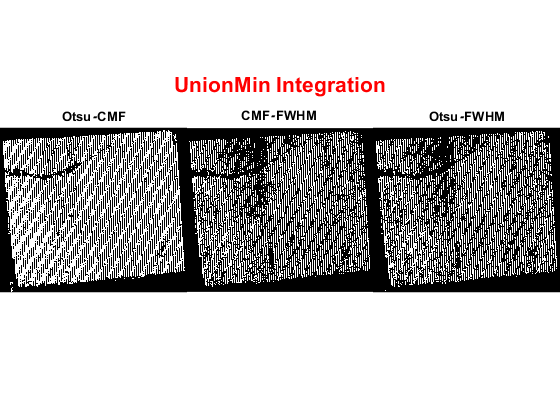

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0 0 0.3333 1]
            Units: 'normalized'

  Show all properties


ax =   1×2 Axes array:

    Axes    Axes


ax =   1×3 Axes array:

    Axes    Axes    Axes


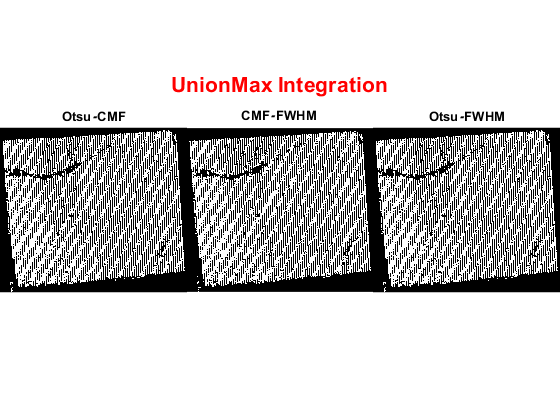

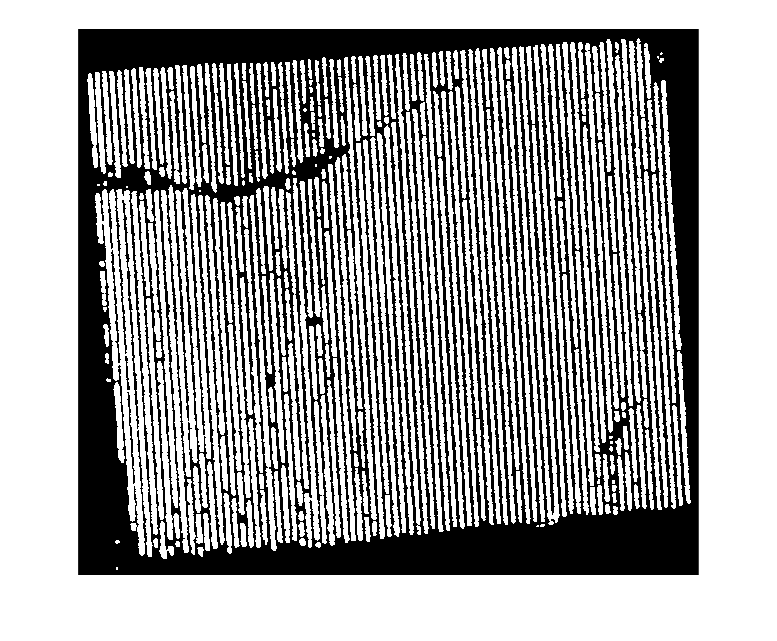

newMin = 26.9902

newMax = 43.7795

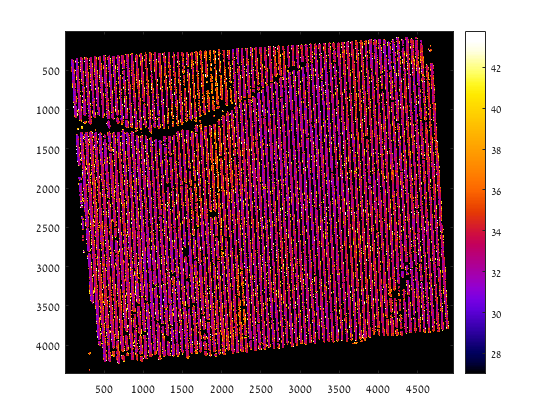

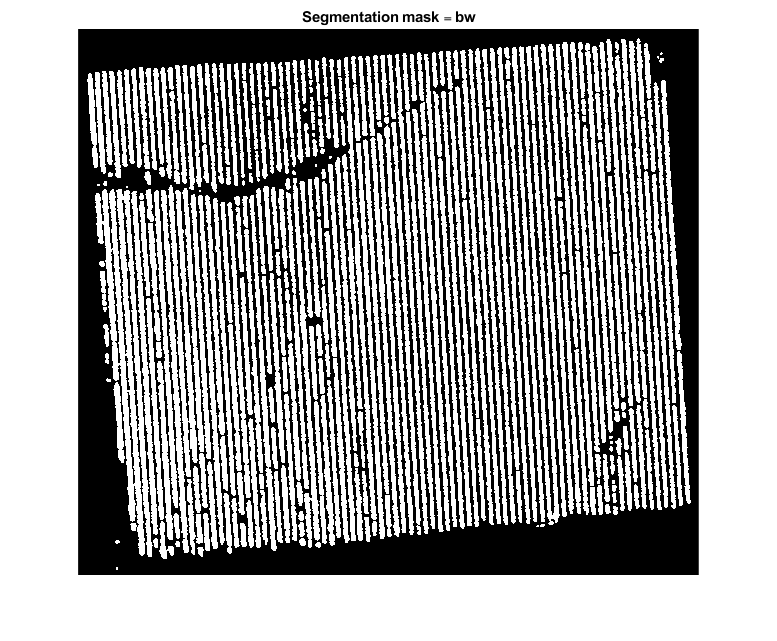

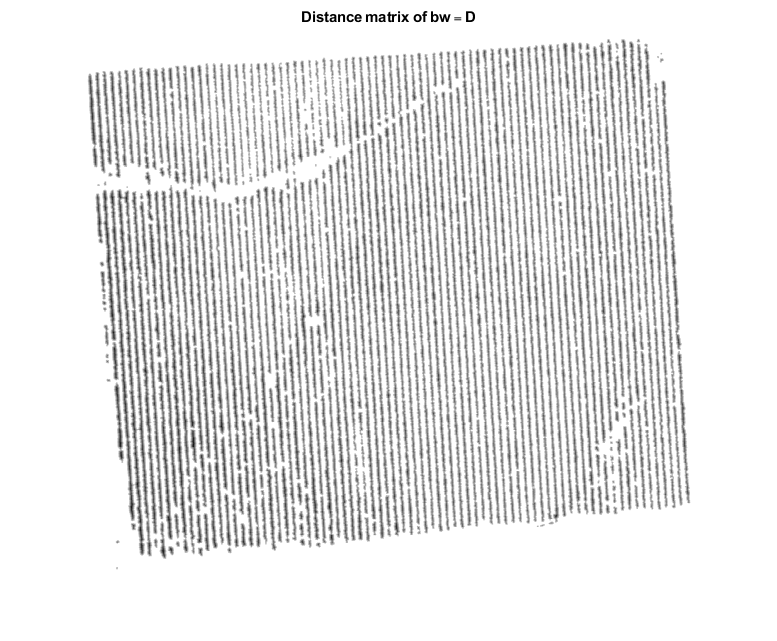

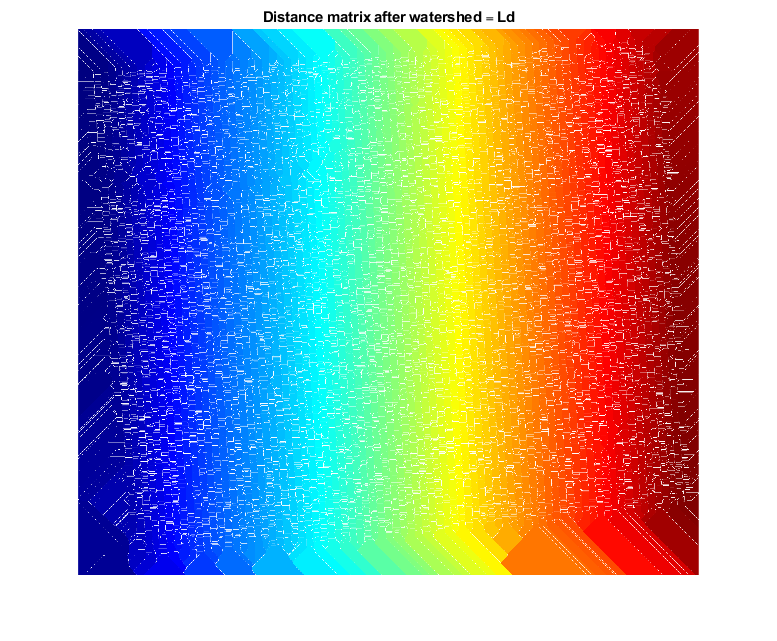

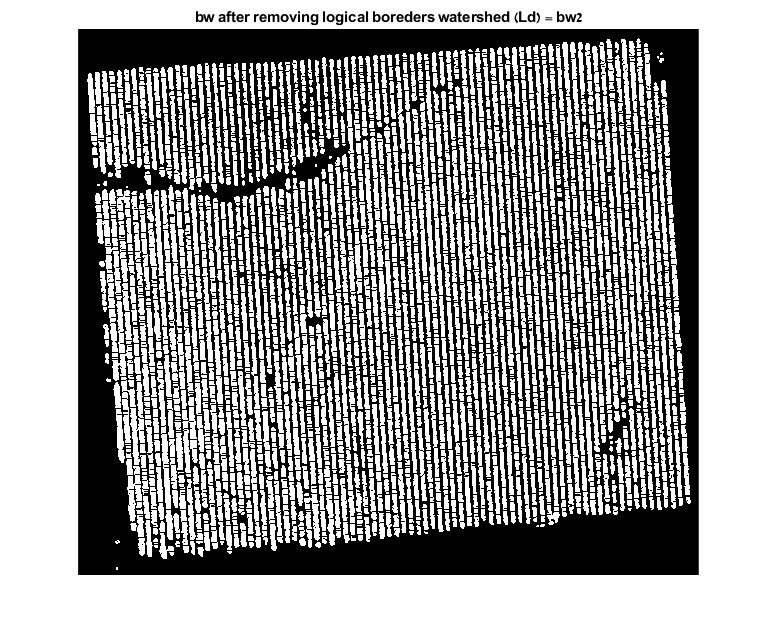

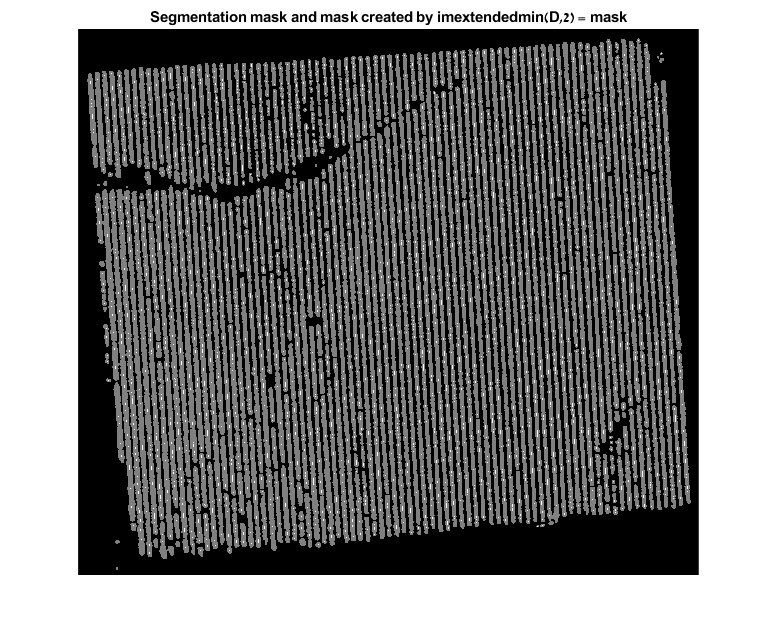

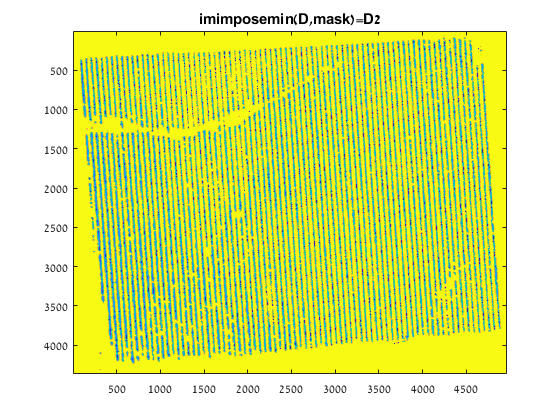

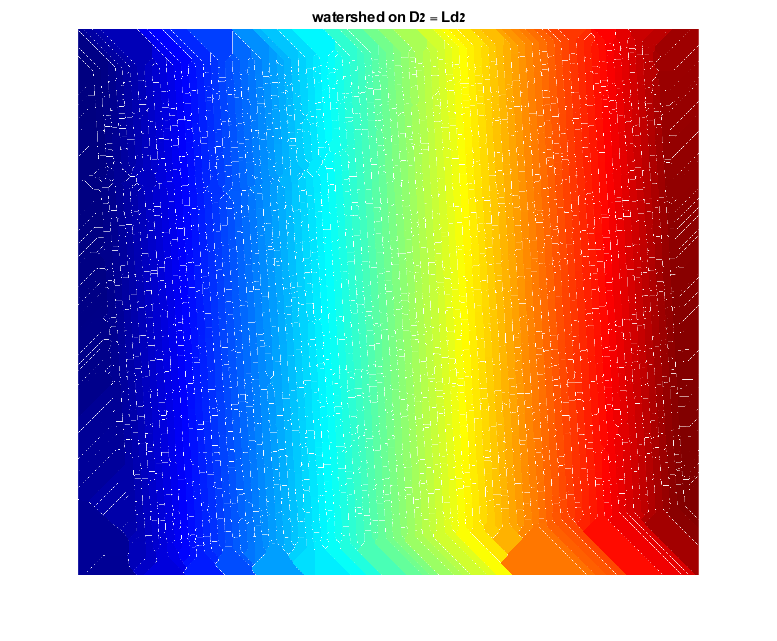

UB_canopy = 33.5945

UB_background = 58.9771

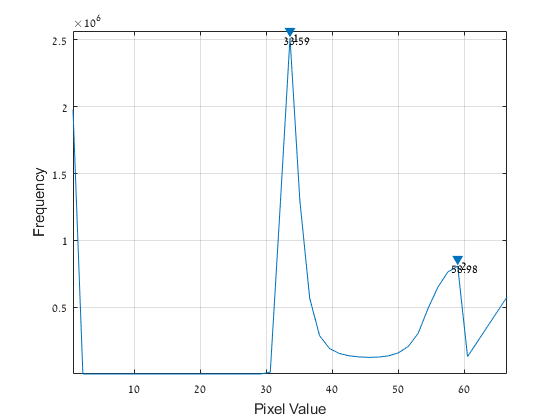

Elapsed time is 36.418117 seconds.


timet = 36.4283

number of iterations = 18. 


   126

     1

    -1

   122

ttrail (x2)=
   34.8794



ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0 0 0.3333 1]
            Units: 'normalized'

  Show all properties


ax =   1×2 Axes array:

    Axes    Axes


ax =   1×3 Axes array:

    Axes    Axes    Axes


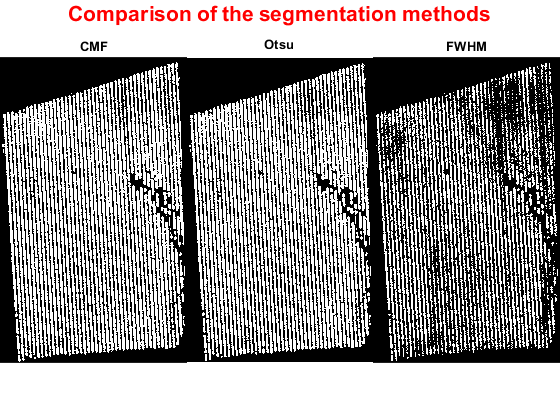

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0 0 0.3333 1]
            Units: 'normalized'

  Show all properties


ax =   1×2 Axes array:

    Axes    Axes


ax =   1×3 Axes array:

    Axes    Axes    Axes


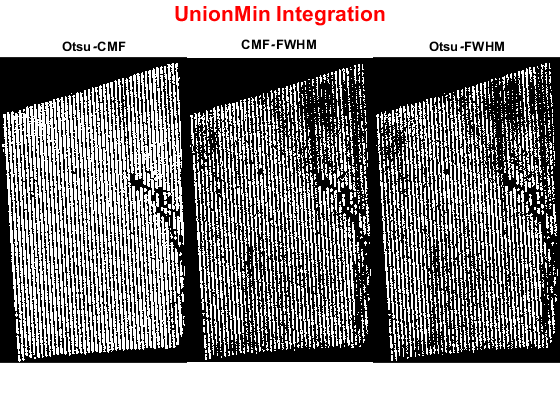

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0 0 0.3333 1]
            Units: 'normalized'

  Show all properties


ax =   1×2 Axes array:

    Axes    Axes


ax =   1×3 Axes array:

    Axes    Axes    Axes


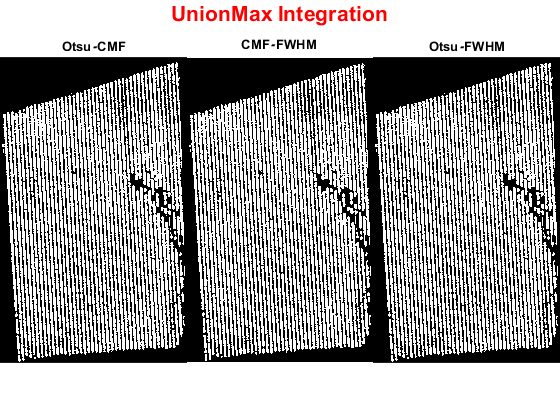

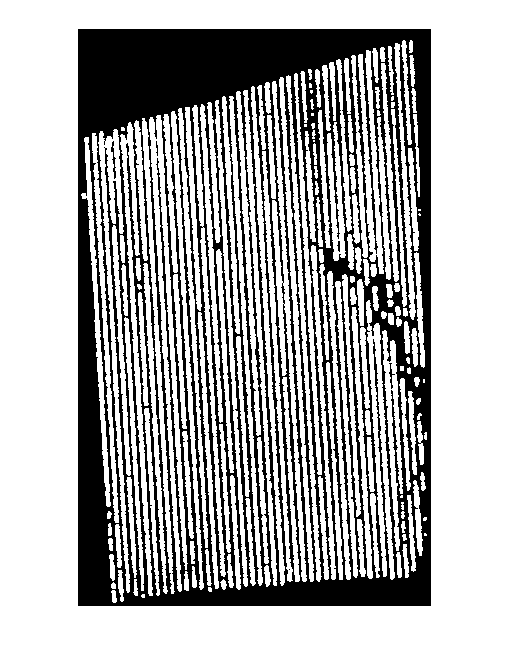

newMin = 29.6901

newMax = 45.4982

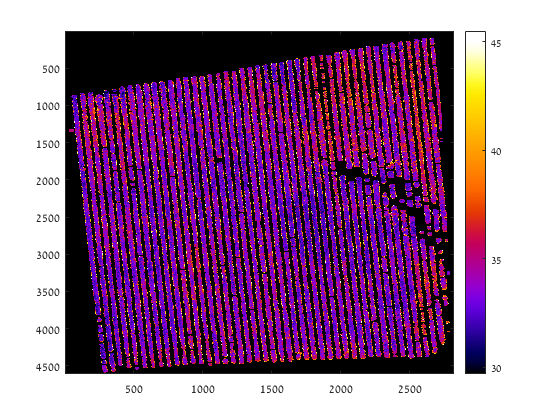

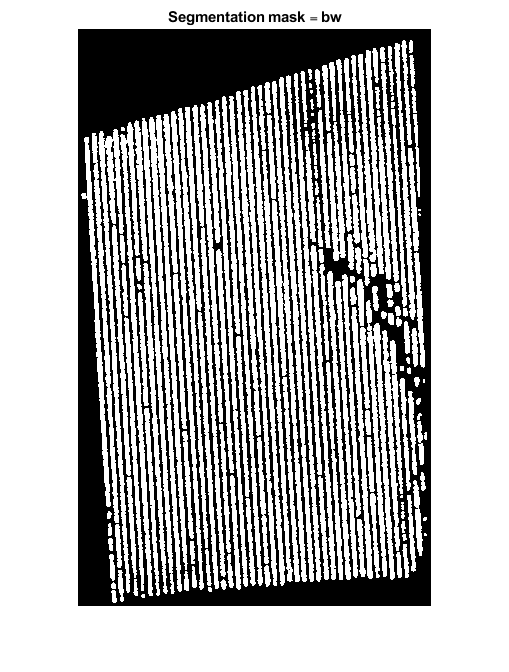

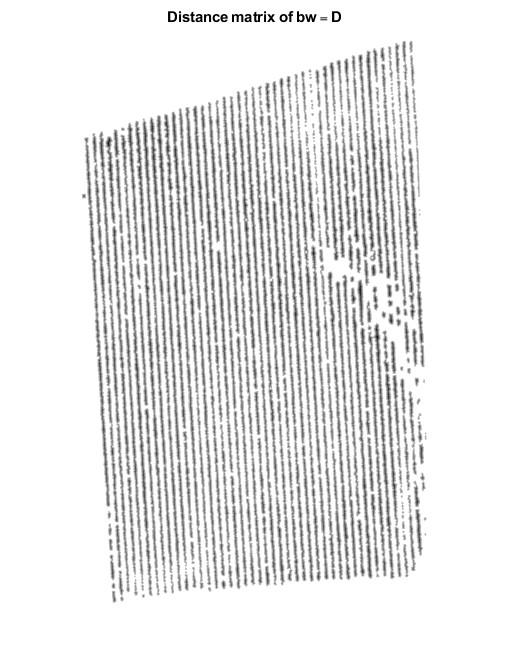

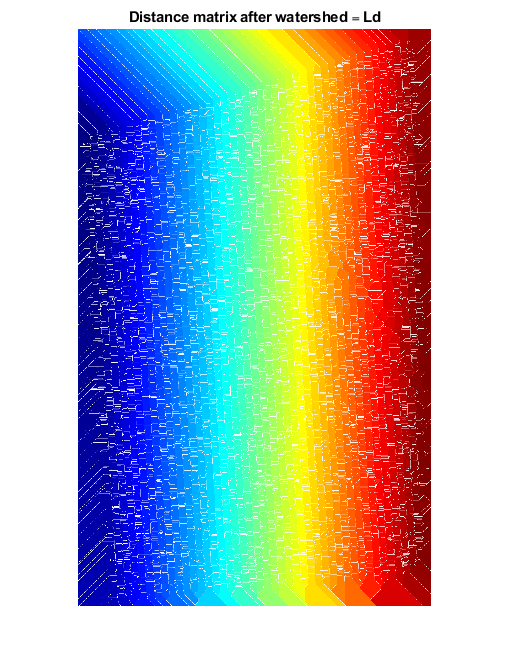

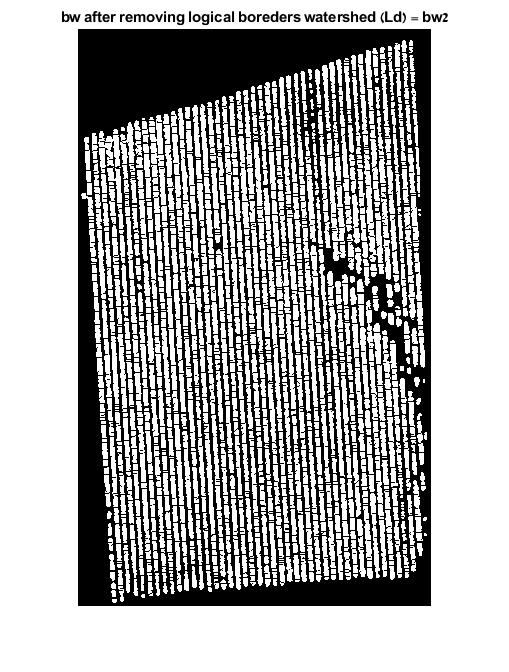

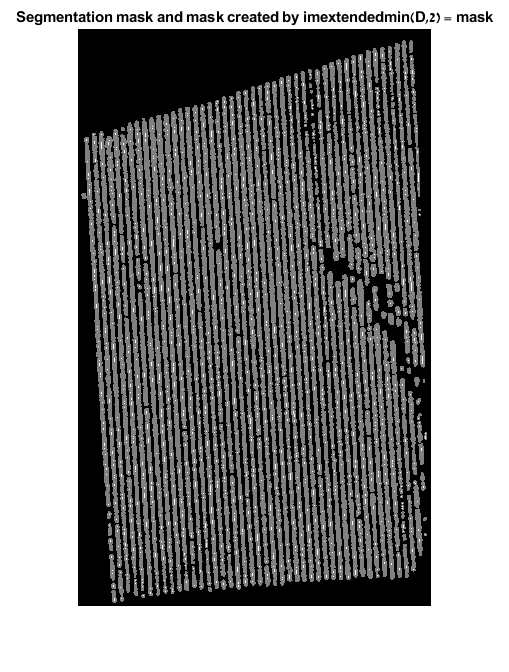

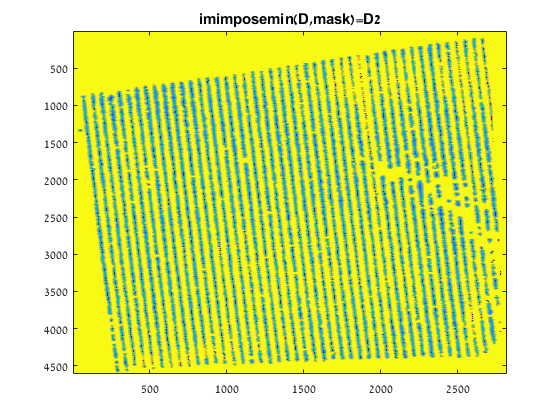

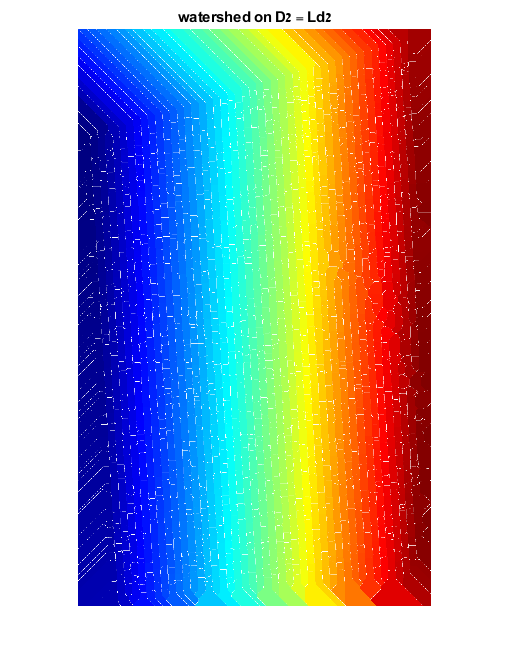

    CC = bwconncomp(bw3);
    L = labelmatrix(CC);
    Lrgb = label2rgb(L,'jet','w','shuffle');
    figure()
    
    Plots_Array{i,1} =[Choosen_segmentaation.*bw3];
    Plots_Array{i,2} = plot_num;
    plot_num=plot_num(1,1);
    image_name= ['Plot_' char(plot_num) '.tif'];   
    mont= montage({uint8(newTIR),Choosen_segmentaation,Lrgb},'Size', [1 3],'ThumbnailSize',[]);

    title({Plot_title;'Original TIR image                          Mask after segmatation                                  Mask after watershed'},'FontSize',13);  
 filename=['C:\Users\Stav\Desktop\school\2\Research\hohoba\results\plot\segmentation\watershed\' image_name];
    imwrite(get(mont,'CData'), filename)
end

  save('Plots_Array_watershed_hohoba_sdeDavid.mat','Plots_Array');

   
    % h3= histogram(final_umixing(:),'BinWidth', 0.2,'BinLimits', [finalmin finalmax],'EdgeColor','none','FaceAlpha',0.6,'FaceColor','#53fca1','LineStyle','-');
    hold on
    h2= histogram(canopy_seg(:),'BinWidth', 0.2,'BinLimits', [newMin newMax],'EdgeColor','none','FaceAlpha',0.3,'FaceColor','#ff796c');
    hold on
    h1= histogram(newTIR(:),'BinWidth', 0.2,'BinLimits', [minT maxT],'FaceAlpha',0.5,'EdgeColor','none','FaceAlpha',0.3,'FaceColor','#d1b26f'); 
    h1.Normalization = 'probability';
    h2.Normalization = 'probability';
    h3.Normalization = 'probability';
    axis tight
    title('Histogram Before and After the Erosion');
xlabel('Pixel Value (Temperature)')
ylabel('Frequency')
% end

function [tif,tfw]=open_Plot_Data(tif_PathName)
    tif=load(tif_PathName).tir_mask;
    tfw_file=strcat(tif_PathName(1:numel(tif_PathName)-3),'tfw');
    tfw=worldfileread(tfw_file,'planar',size(tif));
end
